# Kinematic DH Parameters for 3-link RPR arm

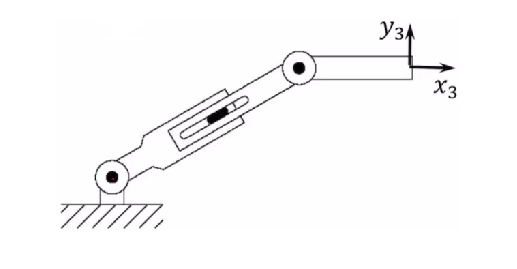

imshow(imread("./figures/RPR.png"))

### Robot Description

- **{r, p, r} : **r for revolute, p for prismatic

- **{0, 0, L_1} : **radius lenghts

- **{Pi/2, -Pi/2, 0} :** link twists

- **{0, q_2, 0} : **link offset rotation

- **{q1, 0, q3} : **joint rotation

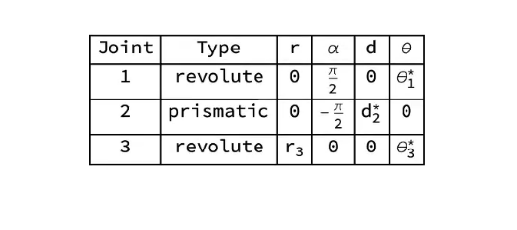

imshow(imread("./figures/DH.png"))

imshow(imread("./figures/annotated_RPR.png"))


$$A_i ={\mathrm{Rot}}_{z,\theta_i } {\mathrm{Trans}}_{z,d_i } {\mathrm{Trans}}_{x,\alpha_i } {\mathrm{Rot}}_{x,\alpha_i }$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i }  & 0 & 0\\
s_{\theta_i }  & c_{\theta_i }  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \alpha_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 1 & 0\\
0 & c_{\alpha_i }  & -s_{\alpha_i }  & 0\\
0 & s_{\alpha_i }  & c_{\alpha_i }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } c_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

Specify the parameters for the system as a matrix. Values come from .

clc
clear
close all


syms t1 d2 Xe Ye ;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            10	     0	        0	    pi-t1 ];


H0_1 = DH(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4))

$$H0\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & \sin\left(t_{1}\right) & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H1_2 = DH(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4))

$$H1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H2_3 = DH(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4))

$$H2\_3 = \left(\begin{array}{cccc} -\cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & -10\,\cos\left(t_{1}\right)\\ \sin\left(t_{1}\right) & -\cos\left(t_{1}\right) & 0 & 10\,\sin\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H0_2 = H0_1*H1_2

$$H0\_2 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & d_{2}\,\sin\left(t_{1}\right)\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_3 = H0_1*H1_2*H2_3

$$H0\_3 = \left(\begin{array}{cccc} -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & 0 & -10\,{\cos\left(t_{1}\right)}^{2}-10\,{\sin\left(t_{1}\right)}^{2}+d_{2}\,\sin\left(t_{1}\right)\\ 0 & -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1_x = simplify(H0_1(1,4))

$$O1\_x = 0$$

O1_y = simplify(H0_1(2,4))

$$O1\_y = 0$$


O2_x = simplify(H0_2(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O2_y = simplify(H0_2(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


O3_x = simplify(H0_3(1,4))

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

O3_y = simplify(H0_3(2,4))

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


xeq = Xe == O3_x

$$xeq = \mathrm{Xe}=d_{2}\,\sin\left(t_{1}\right)-10$$

yeq = Ye == O3_y

$$yeq = \mathrm{Ye}=-d_{2}\,\cos\left(t_{1}\right)$$


S = solve([xeq yeq],[t1 d2])

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]



simplify(S.t1)

$$ans = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

simplify(S.d2)

$$ans = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$


S=subs(S,Ye,sqrt(1800-Xe^2))

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]



t_1 = simplify(S.t1);
d_2 = simplify(S.d2);

t_1(2)

$$ans = 2\,\mathrm{atan}\left(\frac{4.4721\,\sqrt{\mathrm{Xe}+95}+\sqrt{1800-{\mathrm{Xe}}^{2}}}{\mathrm{Xe}+10}\right)$$

d_2(2)

$$ans = 4.4721\,\sqrt{\mathrm{Xe}+95}$$


Xe = 30

Xe = 30


t_1 = eval(t_1)

t_1 =    -0.9273
    2.2143


d_2 = eval(d_2)

d_2 =   -50.0000
   50.0000


t_3 = pi - t_1

t_3 =     4.0689
    0.9273



O1_x = simplify(H0_1(1,4))

$$O1\_x = 0$$

O1_y = simplify(H0_1(2,4))

$$O1\_y = 0$$


O2_x = simplify(H0_2(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O2_y = simplify(H0_2(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


O3_x = simplify(H0_3(1,4))

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

O3_y = simplify(H0_3(2,4))

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


% t1 = deg2rad(180-104.511+90)
% t3 = deg2rad(90-(180-104.511))
% d2 = sqrt(20^2+30^2)

t1 = atan(3/2)+pi/2

t1 = 2.5536

d2 = sqrt(20^2+30^2)

d2 = 36.0555



t1 = t_1(2)

t1 = 2.2143

d2 = d_2(2)

d2 = 50.0000




O2_x = eval(O2_x)

O2_x = 40.0000

O2_y = eval(O2_y)

O2_y = 30.0000


O3_x = eval(O3_x)

O3_x = 30.0000

O3_y = eval(O3_y)

O3_y = 30.0000

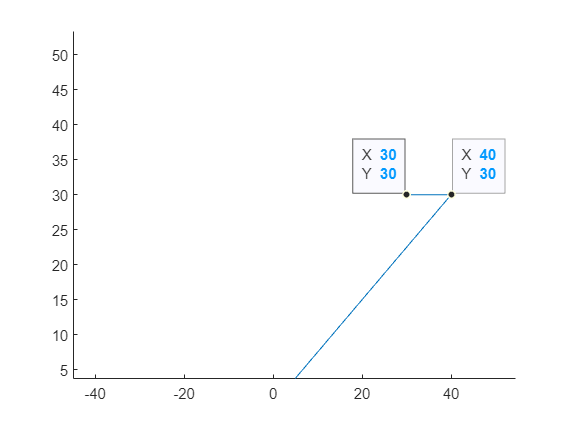


clf
link1 = line([0,O1_x],[0,O1_y]);
link2 = line([O1_x, O2_x],[O1_y, O2_y]);
link3 = line([O2_x, O3_x],[O2_y, O3_y]);
xlim([-60 60])
ylim([0 60])

function [A] = DH(a,alpha,d,theta)

A = [cos(theta) -sin(theta)*round(cos(alpha))  sin(theta)*round(sin(alpha)) a*cos(theta);
     sin(theta)  cos(theta)*round(cos(alpha)) -cos(theta)*round(sin(alpha)) a*sin(theta);
     0           round(sin(alpha))             round(cos(alpha))            d ;
     0           0                             0                            1];
end